## Machine Learning for THz classification of Polymers

### Import Data (feature file)

opts=detectImportOptions("../ml/train/featureFile.csv");
train=readtable("../ml/train/featureFile.csv",opts, ...
                "ReadVariableNames",false);
test=readtable("../ml/test/featureFileTest.csv",opts, ...
                "ReadVariableNames",false);

### Visualize Training Data

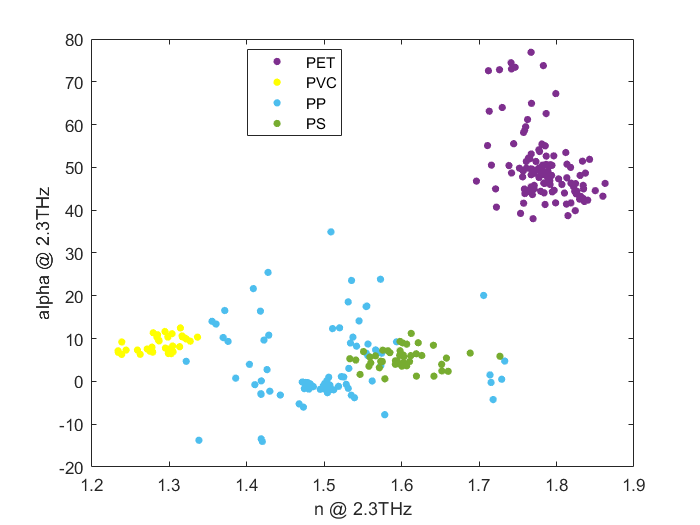

clr=[0.4940 0.1840 0.5560;1 1 0;0.3010 0.7450 0.9330;0.4660 0.6740 0.1880];
gscatter(train.nAt2_3THz,train.alphaAt2_3THz,train.Category,clr)
xlabel('n @ 2.3THz')
ylabel('alpha @ 2.3THz')

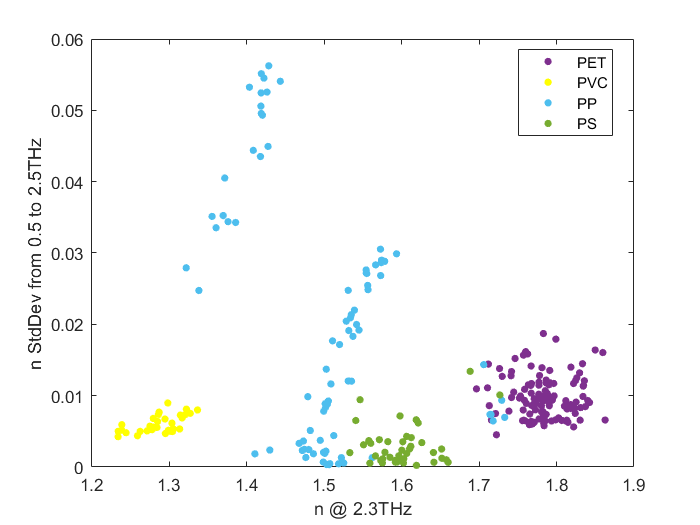

gscatter(train.nAt2_3THz , ...
         train.nStdDevfrom0_5to2_5THz, train.Category,clr)
xlabel('n @ 2.3THz')
ylabel('n StdDev from 0.5 to 2.5THz')

### Create and train model

[modelfinal,validationDataAcc]=trainClassifier(train);
validationDataAcc

validationDataAcc = 0.9856

### 3D Visualization

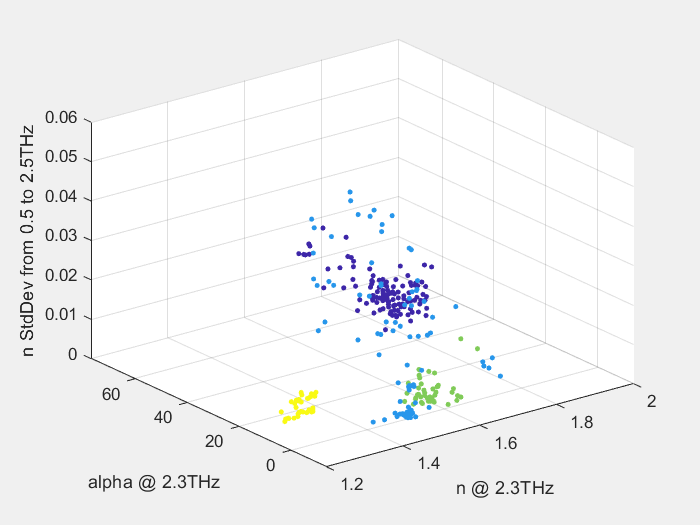

figure
set(gcf,'Visible','on')
scatter3(train.nAt2_3THz,train.alphaAt2_3THz,train.nStdDevfrom0_5to2_5THz,...
    10,categorical(train.Category),'filled')
xlabel('n @ 2.3THz');ylabel('alpha @ 2.3THz');zlabel('n StdDev from 0.5 to 2.5THz');

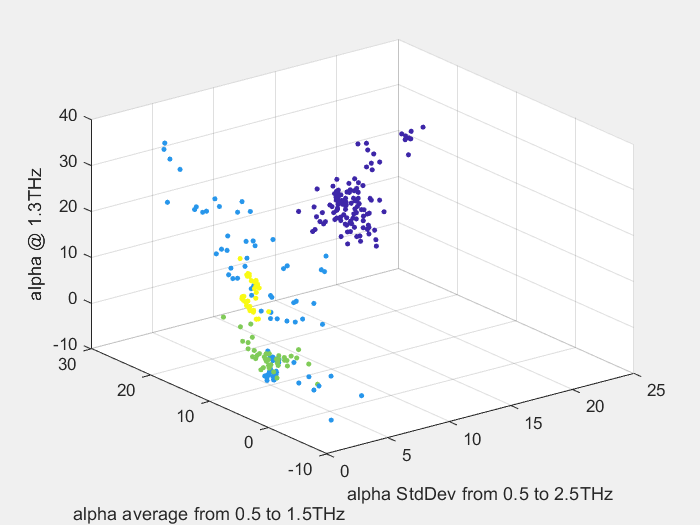


figure
set(gcf,'Visible','on')
scatter3(train.alphaStdDevfrom0_5to2_5THz,train.alphaAvgfrom0_5to1_5THz,train.alphaAt1_3THz,...
    10,categorical(train.Category),'filled')
xlabel('alpha StdDev from 0.5 to 2.5THz');ylabel('alpha average from 0.5 to 1.5THz');zlabel('alpha @ 1.3THz');

### Confusion Matrix of the Taining set

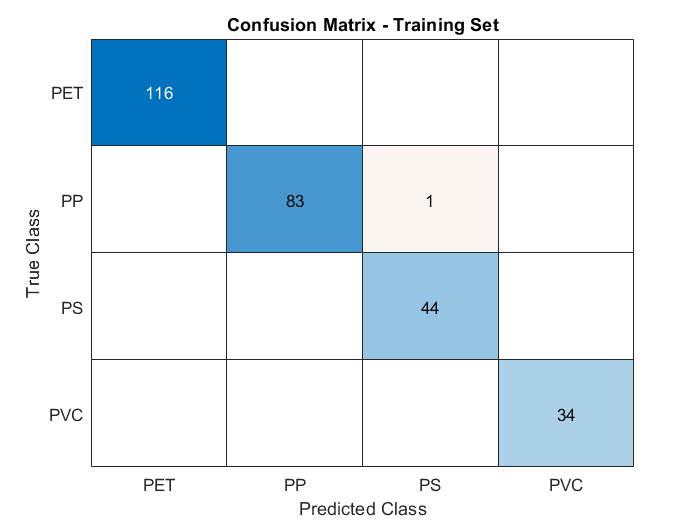

predictionsTrainSet=modelfinal.predictFcn(train);
figure
confusionchart(categorical(train.Category),predictionsTrainSet,'Title','Confusion Matrix - Training Set')

### Test model

tic
predictionsTestSet=modelfinal.predictFcn(test);
toc

Elapsed time is 0.011299 seconds.


TestAcc=sum(predictionsTestSet==test.Category ...
        )/length(predictionsTestSet)

TestAcc = 1

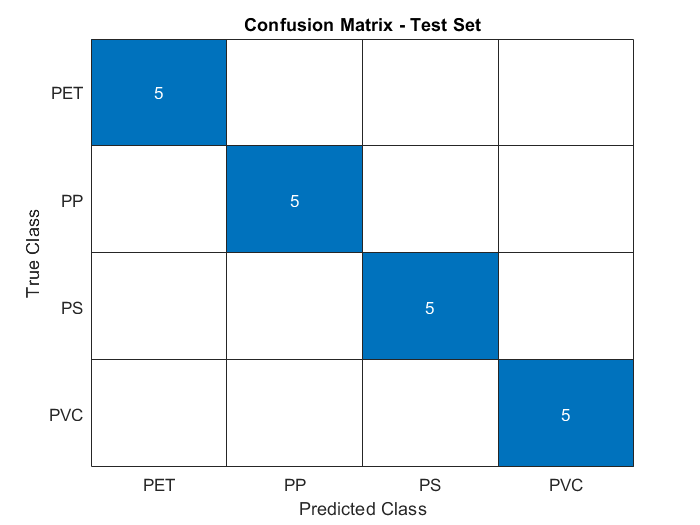

figure
confusionchart(categorical(test.Category),predictionsTestSet,'Title','Confusion Matrix - Test Set')

### Functions

function [trainedClassifier, validationAccuracy] = trainClassifier(trainingData)

inputTable = trainingData;
predictorNames = {'nAt2_3THz', 'alphaAt2_3THz', 'alphaStdDevfrom0_5to2_5THz',...
    'nStdDevfrom0_5to2_5THz', 'alphaAvgfrom0_5to1_5THz', 'alphaAt1_3THz'};
predictors = inputTable(:, predictorNames);
response = inputTable.Category;
isCategoricalPredictor = [false, false, false, false, false, false];

template = templateSVM(...
    'KernelFunction', 'gaussian', ...
    'PolynomialOrder', [], ...
    'KernelScale', 2.4, ...
    'BoxConstraint', 1, ...
    'Standardize', true, ...
    'SaveSupportVectors', true);
classificationSVM = fitcecoc(...
    predictors, ...
    response, ...
    'Learners', template, ...
    'Coding', 'onevsone', ...
    'ClassNames', categorical({'PET'; 'PP'; 'PS'; 'PVC'}));

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
svmPredictFcn = @(x) predict(classificationSVM, x);
trainedClassifier.predictFcn = @(x) svmPredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedClassifier.RequiredVariables = {'alphaAt1_3THz', 'alphaAt2_3THz',...
    'alphaAvgfrom0_5to1_5THz', 'alphaStdDevfrom0_5to2_5THz', 'nAt2_3THz',...
    'nStdDevfrom0_5to2_5THz'};
trainedClassifier.ClassificationSVM = classificationSVM;

% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'nAt2_3THz', 'alphaAt2_3THz',...
    'alphaStdDevfrom0_5to2_5THz', 'nStdDevfrom0_5to2_5THz',...
    'alphaAvgfrom0_5to1_5THz', 'alphaAt1_3THz'};
predictors = inputTable(:, predictorNames);
response = inputTable.Category;
isCategoricalPredictor = [false, false, false, false, false, false];

% Perform cross-validation
partitionedModel = crossval(trainedClassifier.ClassificationSVM, 'KFold', 5);

% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');
end